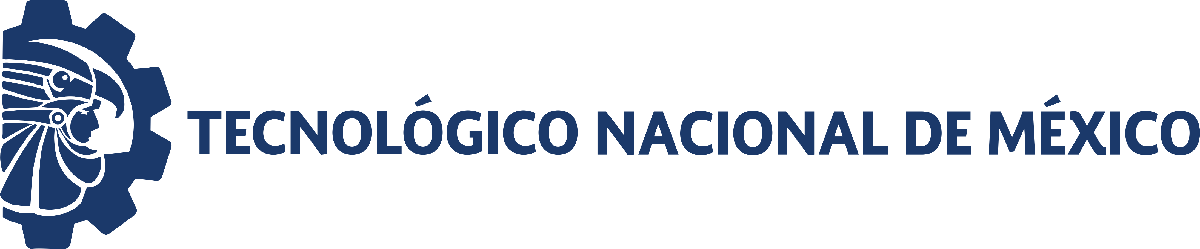                                 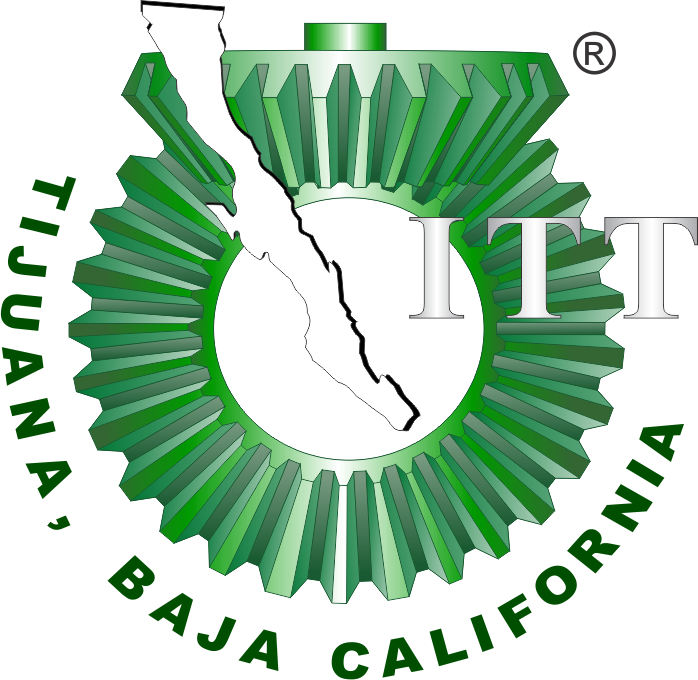

# Práctica 3: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

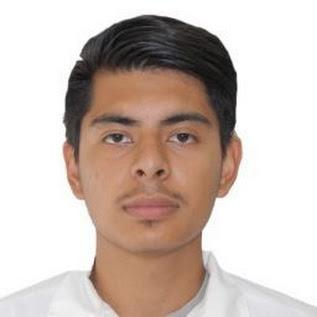

Nombre del alumno: Diego Saul Lopez Islas

Número de control: 22211759

Correo institucional: L22211759@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

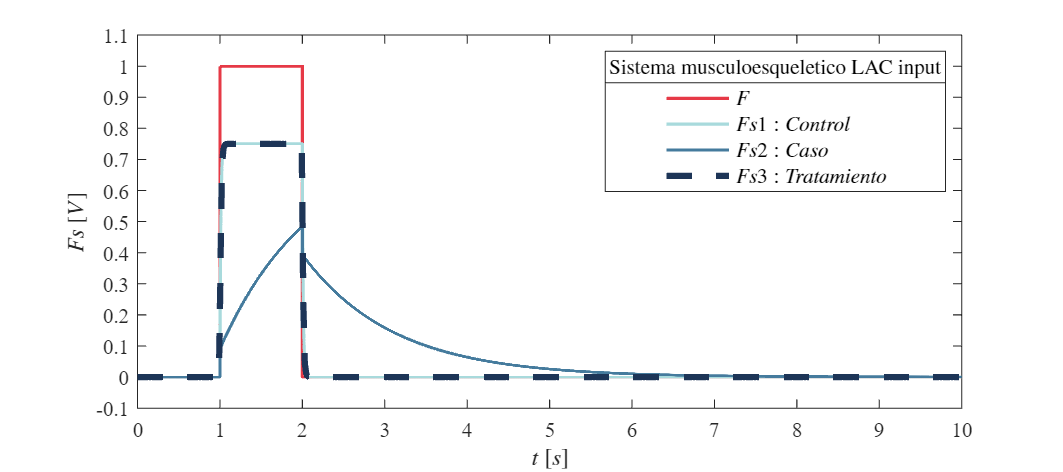

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Simulacion';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
Signal = 'Sistema musculoesqueletico LAC';
Signal2 = 'Sistema musculoesqueletico LA';
set_param('Simulacion/F','Amplitude','1')
set_param('Simulacion/F','Period','10')
set_param('Simulacion/F','PulseWidth','10')
set_param('Simulacion/F','Phasedelay','1')
X = sim(file,parameters);
plotsignals(X.t,X.F,X.Fs1,X.Fs2,X.Fs3,Signal);

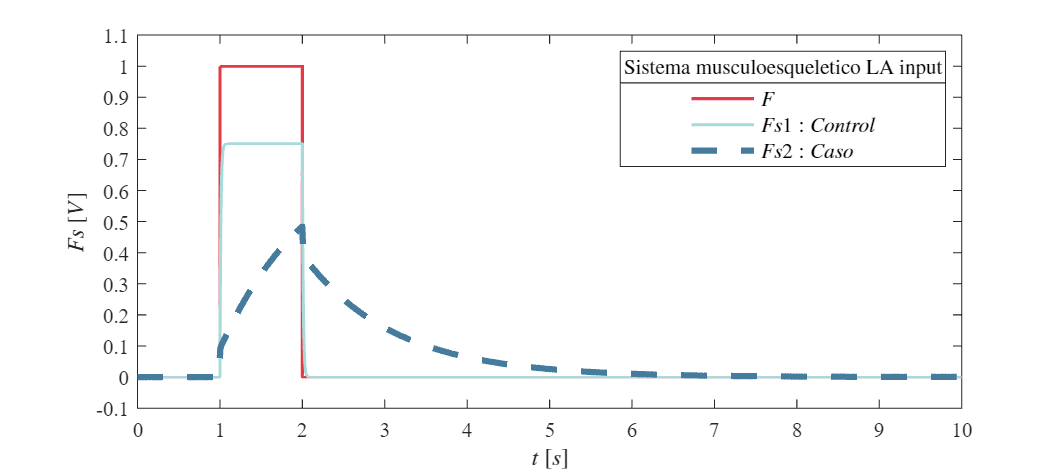

plotsignals2(X.t,X.F,X.Fs1,X.Fs2,Signal2);

**Funcion: Respuesta a las señales**

function plotsignals(t,F,Fs1,Fs2,Fs3,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616
               0.114,0.208,0.341
               0.133,0.341,0.310
               0.569,0.392,0.235];
    colororder(mycolor)
    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,'--',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(4), 'LineWidth',3); 
    L = legend('$F$','$Fs1:Control$','$Fs2:Caso$','$Fs3:Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10);
    title(L,[Signal,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Fs$ $[V]$','Interpreter','Latex','FontSize',11)

   
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')
     
    if Signal == "Sistema musculoesqueletico LAC" 
        xlim([0,10]); xticks(0:1:10);
        ylim([-0.1,1.1]); yticks(-0.1:0.1:10);
    end
 
end
function plotsignals2(t,F,Fs1,Fs2,Signal2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616];
    colororder(mycolor)
    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'--',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3), 'LineWidth',3); 
    L = legend('$F$','$Fs1:Control$','$Fs2:Caso$');
    set(L,'Interpreter','Latex','FontSize',10);
    title(L,[Signal2,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Fs$ $[V]$','Interpreter','Latex','FontSize',11)

    if Signal2 == "Sistema musculoesqueletico LA"
        xlim([0,10]); xticks(0:1:10);
        ylim([-0.1,1.1]); yticks(-0.1:0.1:10);
    end
   
    exportgraphics(gcf,[Signal2,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal2,'.png'],'ContentType','vector')
end
